# Ejercicio en clase - Mapas de colores

¿Todos los mapas de colores representan la información de la misma manera?

¿Hay algunos mapas de colores que representen mejor la información que otros?

Para contestar a estas preguntas, vamos a realizar el siguiente ejercicio. Representa una distirbución espacial de fase de un vórtice de luz, donde la fase $(\varphi)$ varíe azimutalmente entre 0 y 2$\pi$, en la que además, añadimos una pequeña modulación sinusoidal, es decir:


$$\varphi(\phi)=\phi+C\sin\left[ \omega\phi) \right]$$


o en coordenadas cartesianas.


$$\varphi(x,y)=\arctan(y/x)+C\sin\left[ \omega\arctan(y/x) \right]$$


La amplitud de la modulación es C, y su frecuencia $\omega$. Representa este perfil con distintos colormaps predefinidos por Matlab  (jet, hsv, ...), y determina si todos ellos visualizan de la misma manera la información que quieres representar.

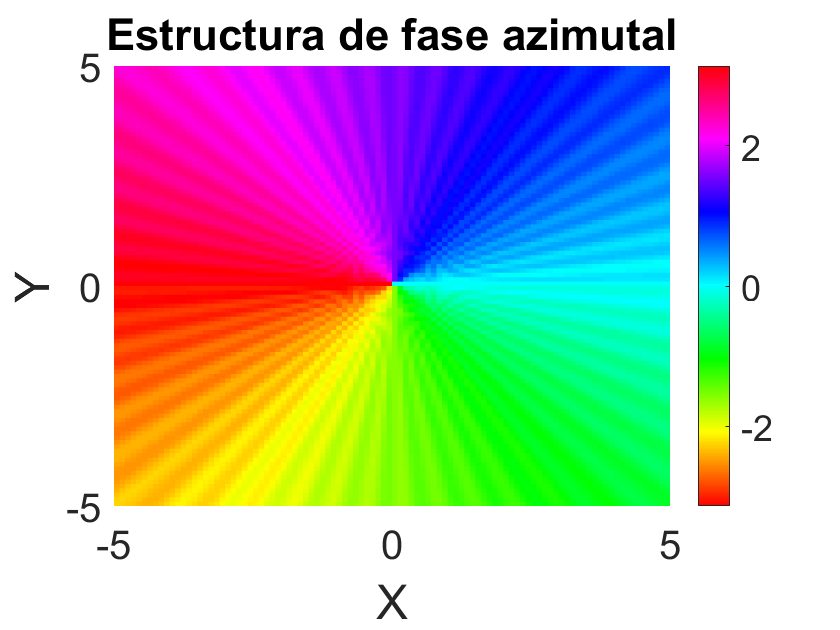

C=0.1;
w=50;
V=exp(-X.^2-Y.^2).*exp(1i*(atan2(Y,X)+C*sin(w*atan2(Y,X))));
surf(x,y,angle(V), 'EdgeColor', 'none','FaceColor','flat','FaceAlpha', 1, 'FaceLighting','phong');
title('Estructura de fase azimutal', 'FontSize', 24, 'FontName','Avenir')
set(gca,'FontSize',20, 'FontName','Avenir')
set(get(gca,'XLabel'),'String','X','FontSize',24,'FontName','Avenir');
set(get(gca,'YLabel'),'String','Y','FontSize',24,'FontName','Avenir');
view(2);
colormap(hsv)
colorbar;

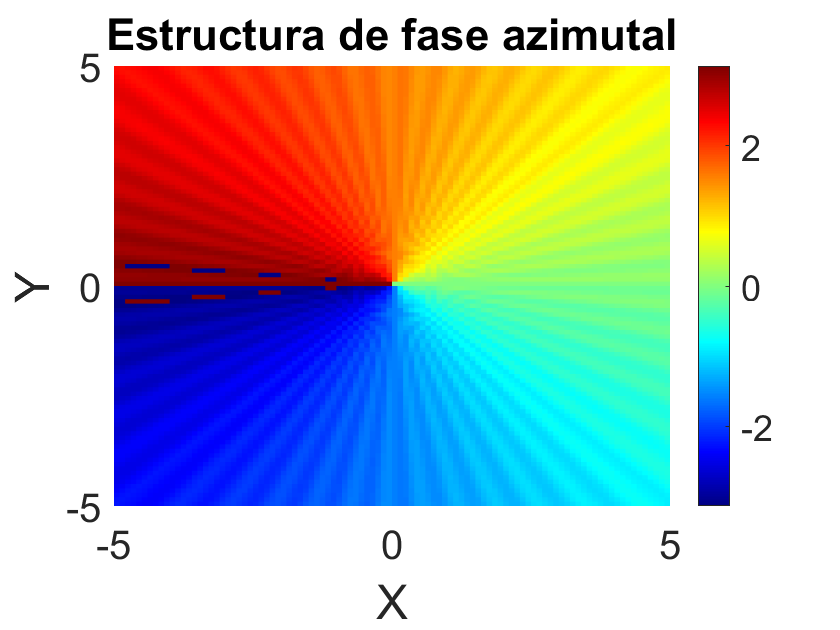

C=0.1;
w=50;
V=exp(-X.^2-Y.^2).*exp(1i*(atan2(Y,X)+C*sin(w*atan2(Y,X))));
surf(x,y,angle(V), 'EdgeColor', 'none','FaceColor','flat','FaceAlpha', 1, 'FaceLighting','phong');
title('Estructura de fase azimutal', 'FontSize', 24, 'FontName','Avenir')
set(gca,'FontSize',20, 'FontName','Avenir')
set(get(gca,'XLabel'),'String','X','FontSize',24,'FontName','Avenir');
set(get(gca,'YLabel'),'String','Y','FontSize',24,'FontName','Avenir');
view(2);
colormap(jet)
colorbar;

# Ejercicio 1 - Mapas de colores

Representa el perfil de fase del ejercicio anterior con colormaps personalizados como los usados en 'colorcet.m'.

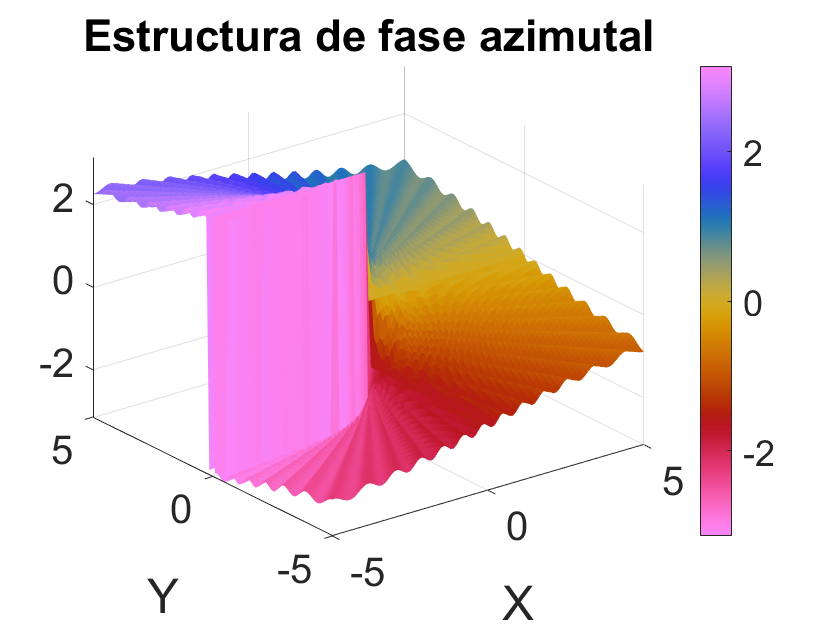

x=-5:0.1:5;
y=-5:0.1:5;
[X,Y]=meshgrid(x,y);
C=0.1;
w=50;
V=exp(-X.^2-Y.^2).*exp(1i*(atan2(Y,X)+C*sin(w.*atan2(Y,X))));
surf(x,y,angle(V), 'EdgeColor', 'none','FaceColor','flat','FaceAlpha', 1, 'FaceLighting','phong');
title('Estructura de fase azimutal', 'FontSize', 24, 'FontName','Avenir');
set(gca,'FontSize',20, 'FontName','Avenir');
set(get(gca,'XLabel'),'String','X','FontSize',24,'FontName','Avenir');
set(get(gca,'YLabel'),'String','Y','FontSize',24,'FontName','Avenir');
colorcet('C1');
colorbar;
view(3);

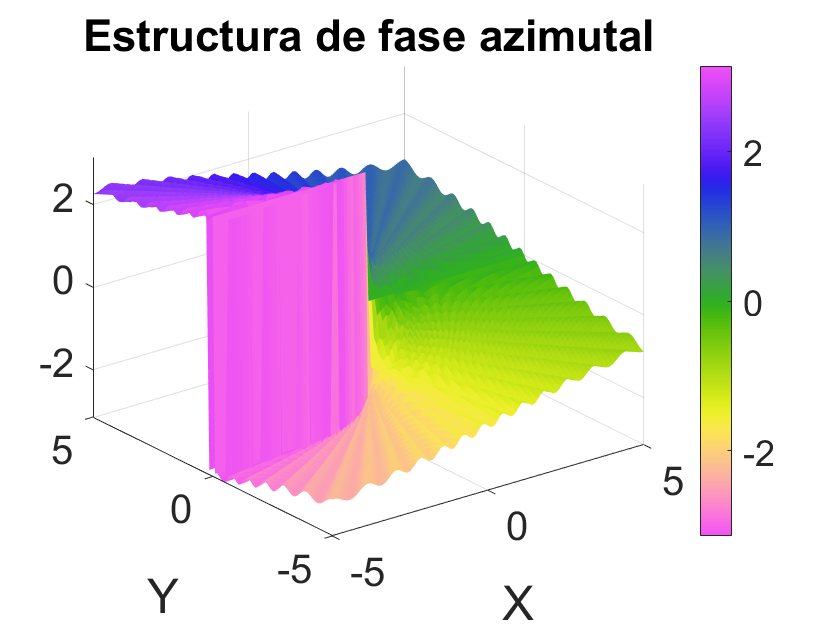


V=exp(-X.^2-Y.^2).*exp(1i*(atan2(Y,X)+C*sin(w.*atan2(Y,X))));
v=surf(x,y,angle(V), 'EdgeColor', 'none','FaceColor','flat','FaceAlpha', 1, 'FaceLighting','phong');
title('Estructura de fase azimutal', 'FontSize', 24, 'FontName','Avenir');
set(gca,'FontSize',20, 'FontName','Avenir');
set(get(gca,'XLabel'),'String','X','FontSize',24,'FontName','Avenir');
set(get(gca,'YLabel'),'String','Y','FontSize',24,'FontName','Avenir');
colorcet('C2');
colorbar;
view(3);

# Ejercicio 2 - Representación de superficies

Considera la función Gaussiana definida en el Live Script del tema anterior. Realiza una representación gráfica de la intensidad, la parte real, y la fase del campo eléctrico en los planos XY y XZ (6 gráficas en total). Utiliza los mapas de colores que creas más adecuados para cada caso, y en alguna de ellas, representa las líneas de contorno. 

- `Intensidad del campo E`

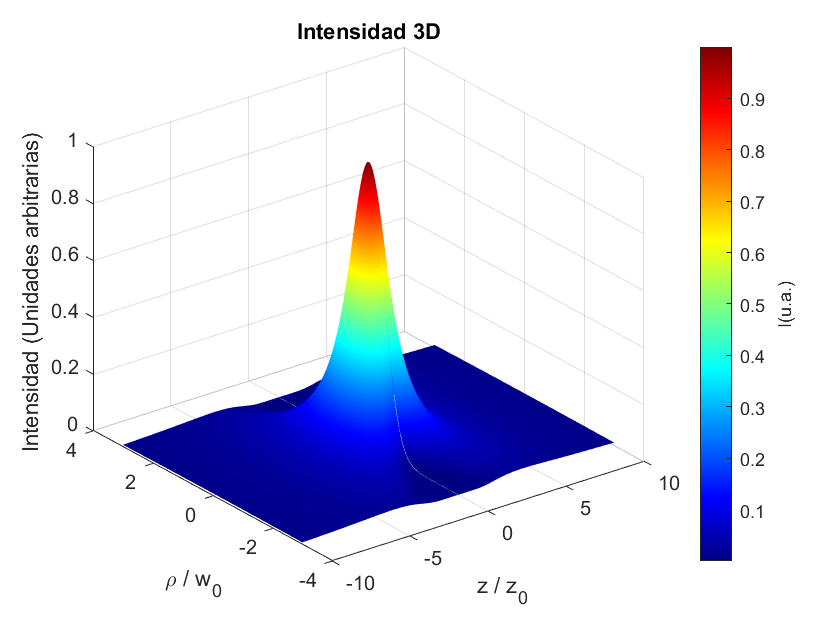

%----------------------Intensidad 3D-------------------------

% Constantes
lan=0.8;
w0=30;
k0=2*pi/lan;
z0=k0*(w0^2)/2;
e0=1;

% Mallado
z=(-10:0.01:10).*z0;
ro=-3*w0:0.5:3*w0;
[ro,z]=meshgrid(ro,z); 
% Con meshgrid creamos dos matrices: ro y z de dimentsiones=lenght(ro)*lenght(z)

% Funciones
fi=atan(z./z0);
w=w0*sqrt(1+(z./z0).^2);
r=(1+(z0./z).^2).*z;
e=e0*(w0./w).*exp(-(ro./w).^2).*exp(-1i*(k0.*z+(k0.*((ro).^2)./(2.*r))-fi));
inten=abs(e).^2;

surf(z/z0,ro/w0,inten,'EdgeColor','none'); % Gráfico de superficie tridimensional.

title('Intensidad 3D', 'FontSize', 16, 'FontName', 'Helvetica');
xlabel(' z / z_{0}', 'FontSize', 12, 'FontName', 'Helvetica');
ylabel(' \rho / w_{0}', 'FontSize', 12, 'FontName', 'Helvetica');
zlabel('Intensidad (Unidades arbitrarias) ', 'FontSize', 12, 'FontName', 'Helvetica');
set(gca, 'FontSize', 10, 'FontName', 'Helvetica');
colormap jet; % establece el mapa de colores de la figura actual
a=colorbar; % La leyenda que nos indica a que valor corresponde cada color
a.Label.String = 'I(u.a.)'; % Etiqueta de la leyenda

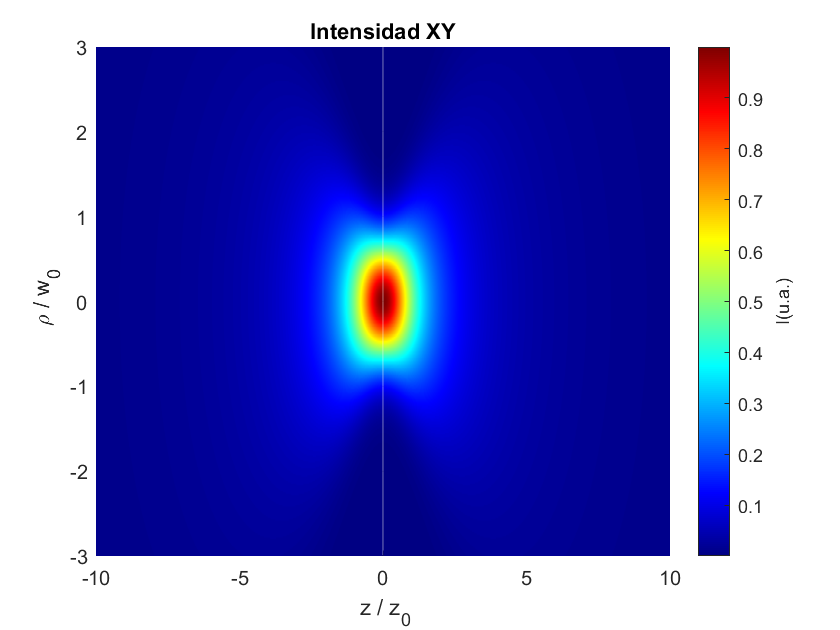


%----------------------Intensidad XY-------------------------
surf(z/z0,ro/w0,inten,'EdgeColor','none');
view(0,90) %Plano Intesidad=0, z=0, Plano XY con estos ejes
title('Intensidad XY', 'FontSize', 16, 'FontName', 'Helvetica');
xlabel(' z / z_{0}', 'FontSize', 12, 'FontName', 'Helvetica');
ylabel(' \rho / w_{0}', 'FontSize', 12, 'FontName', 'Helvetica');
set(gca, 'FontSize', 10, 'FontName', 'Helvetica');
colormap jet;
a=colorbar; 
a.Label.String = 'I(u.a.)';

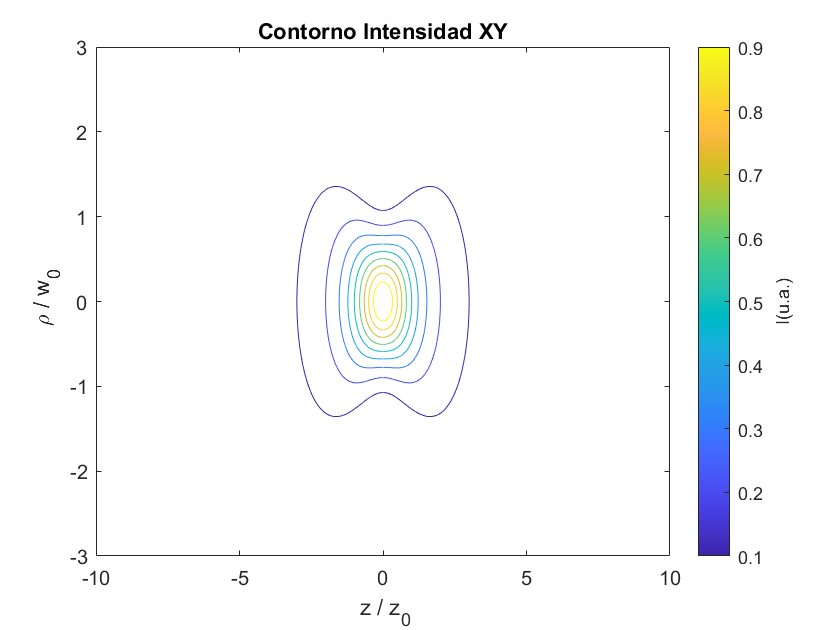


%-----------------Líneas de Contorno Intensidad XZ-------------------------
contour(z/z0,ro/w0,inten) % Trama de contorno muestra isolíneas de matriz inten
% utilizando z/z0 y ro/w0 para determinar el valores de x y y 
title('Contorno Intensidad XY', 'FontSize', 16, 'FontName', 'Helvetica');
xlabel(' z / z_{0}', 'FontSize', 12, 'FontName', 'Helvetica');
ylabel(' \rho / w_{0}', 'FontSize', 12, 'FontName', 'Helvetica');
set(gca, 'FontSize', 10, 'FontName', 'Helvetica');
colormap(parula)
a=colorbar; 
a.Label.String = 'I(u.a.)';

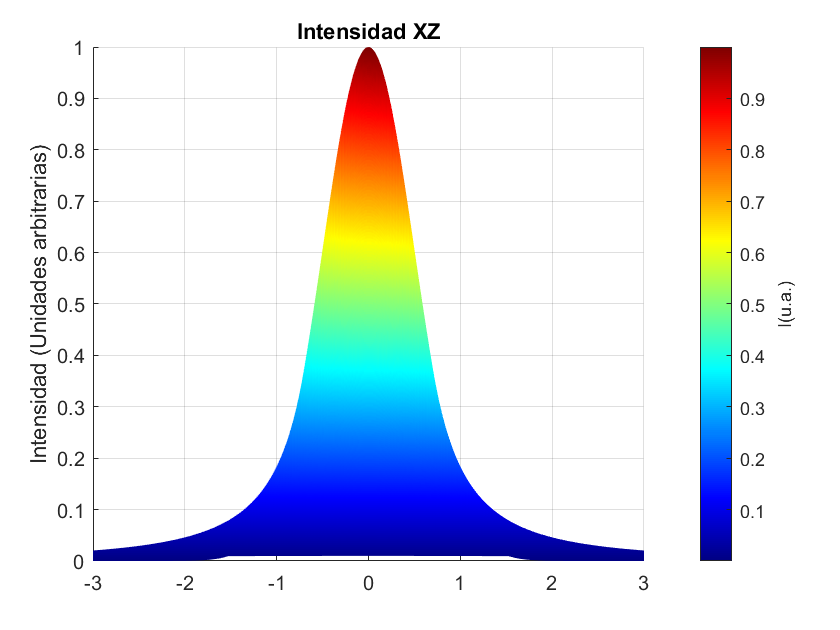


%----------------------Intensidad XZ-------------------------
surf(z/z0,ro/w0,inten,'EdgeColor','none');
view(90,0) %Plano ro=0, y=0, Plano XZ con estos ejes
title('Intensidad XZ', 'FontSize', 16, 'FontName', 'Helvetica');
xlabel(' z / z_{0}', 'FontSize', 12, 'FontName', 'Helvetica');
zlabel('Intensidad (Unidades arbitrarias)' , 'FontSize', 12, 'FontName', 'Helvetica');
set(gca, 'FontSize', 10, 'FontName', 'Helvetica');
colormap jet;
a=colorbar; 
a.Label.String = 'I(u.a.)';

- `Parte real del campo E`

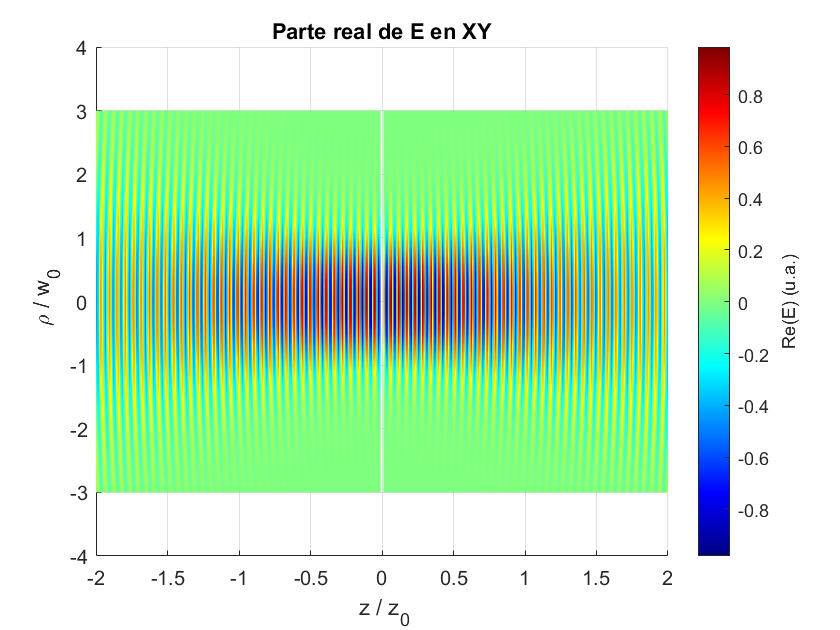

%----------------------Parte real del campo XY-------------------------
surf(z/z0,ro/w0,real(e),'EdgeColor','none');
view(0,90) %Plano Parte real del campo=0, z=0, Plano XY con estos ejes
title('Parte real de E en XY', 'FontSize', 16, 'FontName', 'Helvetica');
xlabel(' z / z_{0}', 'FontSize', 12, 'FontName', 'Helvetica');
ylabel(' \rho / w_{0}', 'FontSize', 12, 'FontName', 'Helvetica');
set(gca, 'FontSize', 10, 'FontName', 'Helvetica');
xlim([-2 2])
ylim([-4 4])
colormap jet;
a=colorbar; 
a.Label.String = 'Re(E) (u.a.)';

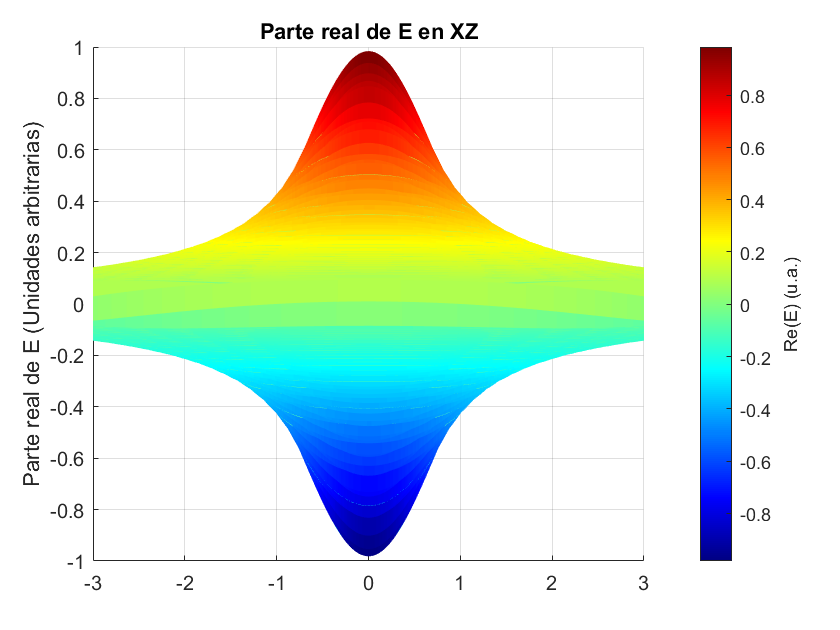


%----------------------Parte real del campo XZ-------------------------
surf(z/z0,ro/w0,real(e),'EdgeColor','none');
view(90,0) %Plano ro=0, y=0, Plano XZ con estos ejes
title('Parte real de E en XZ', 'FontSize', 16, 'FontName', 'Helvetica');
xlabel(' z / z_{0}', 'FontSize', 12, 'FontName', 'Helvetica');
zlabel('Parte real de E (Unidades arbitrarias)' , 'FontSize', 12, 'FontName', 'Helvetica');
set(gca, 'FontSize', 10, 'FontName', 'Helvetica');
colormap jet;
a=colorbar; 
a.Label.String = 'Re(E) (u.a.)';

- `Fase del campo E`

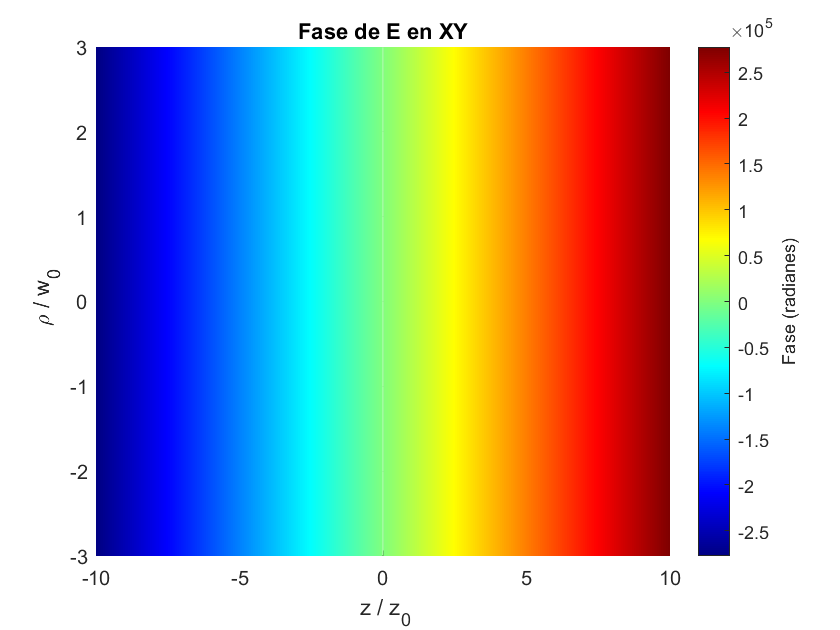

fase=(k0.*z+(k0.*((ro).^2)./(2.*r))-fi);

%----------------------Fase del campo XY-------------------------
surf(z/z0,ro/w0,fase,'EdgeColor','none');
view(0,90) %Plano Fase del campo=0, z=0, Plano XY con estos ejes
title('Fase de E en XY', 'FontSize', 16, 'FontName', 'Helvetica');
xlabel(' z / z_{0}', 'FontSize', 12, 'FontName', 'Helvetica');
ylabel(' \rho / w_{0}', 'FontSize', 12, 'FontName', 'Helvetica');
set(gca, 'FontSize', 10, 'FontName', 'Helvetica');
colormap jet;
a=colorbar; 
a.Label.String = 'Fase (radianes)';

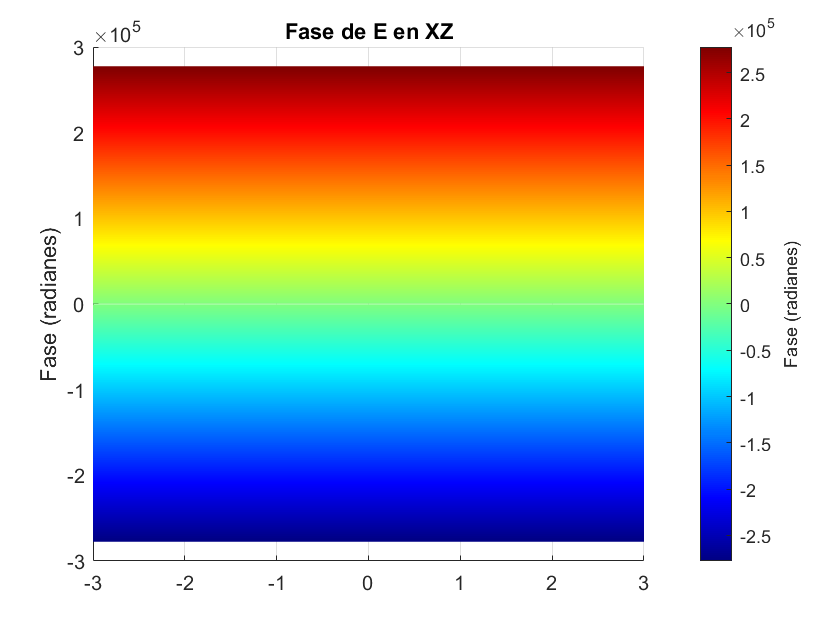


%----------------------Fase del campo XZ-------------------------
surf(z/z0,ro/w0,fase,'EdgeColor','none');
view(90,0) %Plano ro=0, y=0, Plano XZ con estos ejes
title('Fase de E en XZ', 'FontSize', 16, 'FontName', 'Helvetica');
xlabel(' z / z_{0}', 'FontSize', 12, 'FontName', 'Helvetica');
zlabel('Fase (radianes)' , 'FontSize', 12, 'FontName', 'Helvetica');
set(gca, 'FontSize', 10, 'FontName', 'Helvetica');
colormap jet;
a=colorbar; 
a.Label.String = 'Fase (radianes)';

# Ejercicio 3 - Representación de volumenes

Considera la función Gaussiana definida en el Live Script del tema anterior. Realiza una representación en volumen XYZ de un valor de la intensidad, otro de la parte real, y otro de la fase del campo eléctrico (3 gráficas en total). Para una mejor visualización, coloca el eje Z a lo largo de la dirección horizontal. 

%%Constantes
lan=0.8;
w0=30;
k0=2*pi/lan;
z0=k0*(w0^2)/2;
e0=1;

%%Mallado
X=-4*w0:w0/5:4*w0;
Y=-4*w0:w0/5:4*w0;
Z=-4*z0-z0/10000:z0/5:4*z0;
[x,y,z] = meshgrid(X,Y,Z); 

%%Funciones
fi=atan(z./z0);
r=(1+(z0./z).^2).*z;
fase=(k0.*z+(k0.*(x.^2+y.^2)./(2.*r))-fi)

fase = fase(:,:,1) =

   1.0e+05 *

   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104
   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104
   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104   -1.1104  

w=w0*sqrt(1+(z./z0).^2);
ef=e0*(w0./w).*exp(-(x.^2+y.^2)./(w).^2).*exp(-1i*(k0.*z+(k0.*(x.^2+y.^2)./(2.*r))-fi))

ef = ef(:,:,1) =

   0.0281 - 0.0239i   0.0194 - 0.0355i   0.0066 - 0.0437i  -0.0085 - 0.0472i  -0.0244 - 0.0457i  -0.0393 - 0.0396i  -0.0519 - 0.0295i  -0.0614 - 0.0165i  -0.0674 - 0.0018i  -0.0699 + 0.0134i  -0.0693 + 0.0282i  -0.0660 + 0.0419i  -0.0609 + 0.0540i  -0.0546 + 0.0643i  -0.0478 + 0.0727i  -0.0410 + 0.0792i  -0.0349 + 0.0842i  -0.0298 + 0.0877i  -0.0259 + 0.0901i  -0.0235 + 0.0914i  -0.0227 + 0.0919i  -0.0235 + 0.0914i  -0.0259 + 0.0901i  -0.0298 + 0.0877i  -0.0349 + 0.0842i  -0.0410 + 0.0792i  -0.0478 + 0.0727i  -0.0546 + 0.0643i  -0.0609 + 0.0540i  -0.0660 + 0.0419i  -0.0693 + 0.0282i  -0.0699 + 0.0134i  -0.0674 - 0.0018i  -0.0614 - 0.0165i  -0.0519 - 0.0295i  -0.0393 - 0.0396i  -0.0244 - 0.0457i  -0.0085 - 0.0472i   0.0066 - 0.0437i   0.0194 - 0.0355i   0.0281 - 0.0239i
   0.0194 - 0.0355i   0.0058 - 0.0440i  -0.0104 - 0.0473i  -0.0273 - 0.0449i  -0.0429 - 0.0372i  -0.0557 - 0.0250i  -0.0647 - 0.0097i  -0.0693 + 0.0073i  -0.0697 + 0.0246i  -0.0663 + 0.0412i  -0.0598 + 

inten=abs(ef).^2

inten = inten(:,:,1) =

    0.0014    0.0016    0.0019    0.0023    0.0027    0.0031    0.0036    0.0040    0.0045    0.0051    0.0056    0.0061    0.0066    0.0071    0.0076    0.0080    0.0083    0.0086    0.0088    0.0089    0.0090    0.0089    0.0088    0.0086    0.0083    0.0080    0.0076    0.0071    0.0066    0.0061    0.0056    0.0051    0.0045    0.0040    0.0036    0.0031    0.0027    0.0023    0.0019    0.0016    0.0014
    0.0016    0.0020    0.0023    0.0028    0.0032    0.0037    0.0043    0.0049    0.0055    0.0061    0.0067    0.0073    0.0080    0.0085    0.0091    0.0096    0.0100    0.0103    0.0106    0.0107    0.0108    0.0107    0.0106    0.0103    0.0100    0.0096    0.0091    0.0085    0.0080    0.0073    0.0067    0.0061    0.0055    0.0049    0.0043    0.0037    0.0032    0.0028    0.0023    0.0020    0.0016
    0.0019    0.0023    0.0028    0.0033    0.0038    0.0044    0.0051    0.0058    0.0065    0.0072    0.0080    0.0087    0.0095    0.0102    0.0108    

partereal=real(ef)

partereal = partereal(:,:,1) =

    0.0281    0.0194    0.0066   -0.0085   -0.0244   -0.0393   -0.0519   -0.0614   -0.0674   -0.0699   -0.0693   -0.0660   -0.0609   -0.0546   -0.0478   -0.0410   -0.0349   -0.0298   -0.0259   -0.0235   -0.0227   -0.0235   -0.0259   -0.0298   -0.0349   -0.0410   -0.0478   -0.0546   -0.0609   -0.0660   -0.0693   -0.0699   -0.0674   -0.0614   -0.0519   -0.0393   -0.0244   -0.0085    0.0066    0.0194    0.0281
    0.0194    0.0058   -0.0104   -0.0273   -0.0429   -0.0557   -0.0647   -0.0693   -0.0697   -0.0663   -0.0598   -0.0511   -0.0410   -0.0305   -0.0203   -0.0108   -0.0026    0.0040    0.0089    0.0119    0.0129    0.0119    0.0089    0.0040   -0.0026   -0.0108   -0.0203   -0.0305   -0.0410   -0.0511   -0.0598   -0.0663   -0.0697   -0.0693   -0.0647   -0.0557   -0.0429   -0.0273   -0.0104    0.0058    0.0194
    0.0066   -0.0104   -0.0283   -0.0447   -0.0579   -0.0665   -0.0699   -0.0684   -0.0623   -0.0526   -0.0404   -0.0267   -0.0126    0.0012    0.


%----------------------Intensidad del campo-------------------------
isovalue=0.1;
figure
hpatch =patch(isosurface(z./z0,x./w0,y./w0,inten,isovalue)) 

hpatch =   Patch with properties:

    FaceColor: [0 0 0]
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: '-'
        Faces: [3520×3 double]
     Vertices: [1762×3 double]

  Show all properties


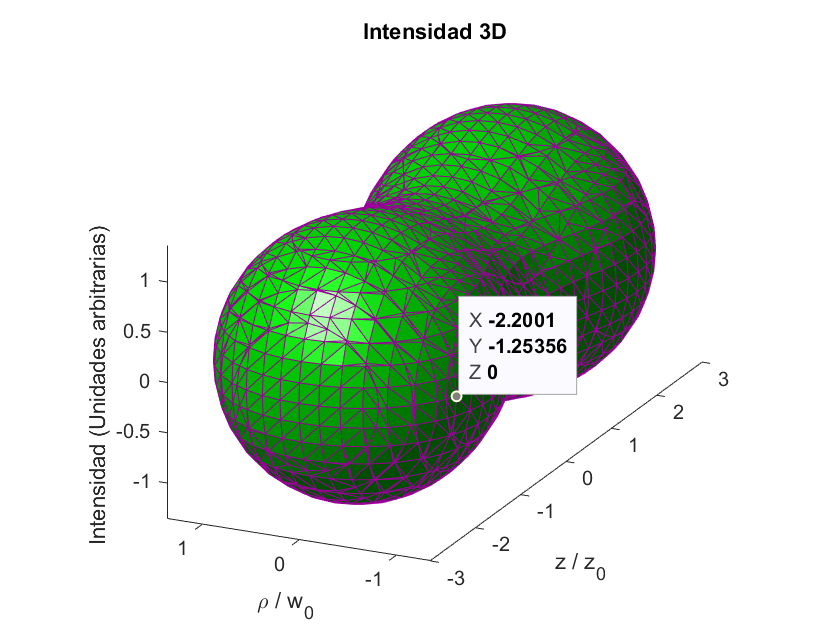

% La función isosuperficie calcula y dibuja una superficie conectando puntos
% de un valor constante dentro de un volumen de espacio y devuelve
% los datos de caras y vértices de la superficie resultante en una estructura. 
% A continuación, traza los datos de las caras y los vértices pasando los 
% datos de la estructura a la función patch. patch lo dibuja conectando los
% vértices.
set(hpatch,'FaceColor','green','EdgeColor','[0.6 0 0.6]')
% set establece algunas propiedades gráficas de la figura creada:
% color de las caras y de los vércices
title('Intensidad 3D', 'FontSize', 16, 'FontName', 'Helvetica');
xlabel(' z / z_{0}', 'FontSize', 12, 'FontName', 'Helvetica');
ylabel(' \rho / w_{0}', 'FontSize', 12, 'FontName', 'Helvetica');
zlabel('Intensidad (Unidades arbitrarias) ', 'FontSize', 12, 'FontName', 'Helvetica');
set(gca, 'FontSize', 10, 'FontName', 'Helvetica');
daspect([1,1,1])
view([-65,20])
axis tight
camlight left; 


%----------------------Parte real del campo-------------------------
isovalue=0.3;
figure
hpatch = patch(isosurface(z./z0,x./w0,y./w0,partereal,isovalue))
set(hpatch,'FaceColor','[1 0 0]','EdgeColor','blue')
title('Parte real de E', 'FontSize', 16, 'FontName', 'Helvetica');
xlabel(' z / z_{0}', 'FontSize', 12, 'FontName', 'Helvetica');
ylabel(' \rho / w_{0}', 'FontSize', 12, 'FontName', 'Helvetica');
zlabel('Parte real de E (Unidades arbitrarias) ', 'FontSize', 12, 'FontName', 'Helvetica');
set(gca, 'FontSize', 10, 'FontName', 'Helvetica');
daspect([1,1,1])
view([-65,20])
axis tight
camlight left; 


%----------------------Fase del campo-----------------------------
isovalue=10;
figure
hpatch = patch(isosurface(z./z0,x./w0,y./w0,fase,isovalue))
set(hpatch,'FaceColor','blue','EdgeColor','magenta')
title('Fase de E', 'FontSize', 16, 'FontName', 'Helvetica');
xlabel(' z / z_{0}', 'FontSize', 12, 'FontName', 'Helvetica');
ylabel(' \rho / w_{0}', 'FontSize', 12, 'FontName', 'Helvetica');
zlabel('Fase de E  (radianes)', 'FontSize', 12, 'FontName', 'Helvetica');
set(gca, 'FontSize', 10, 'FontName', 'Helvetica');
view([-65,20])
axis tight
camlight left; 
